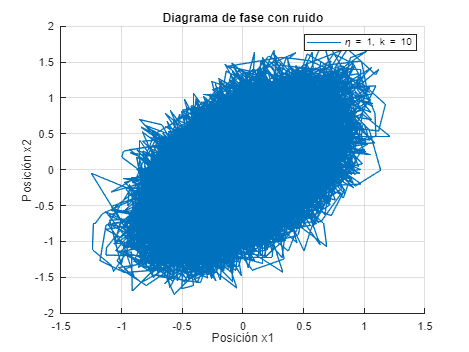

% Parámetros del sistema
m = 1;              % Masa
eta = 1;  % Valores de eta (coef. de fricción)
k = 10;  % Valores de k1        
x1_0 = 0;           % Posición inicial de la primera partícula
x2_0 = 0;           % Posición inicial de la segunda partícula
tspan = [0, 1000];      % Tiempo total de simulación
dt = 0.01;            % Paso de tiempo
N = tspan(2) / dt;    % Número de pasos
t = linspace(tspan(1), tspan(2), N);  % Vector de tiempo
kb = 1;               % Constante de Boltzmann
T1 = 1;  % Valores de temperatura
T2 = 3;
% Inicialización de variables
x1 = zeros(1, N); % Posición de la primera partícula
x2 = zeros(1, N); % Posición de la segunda partícula
x1(1) = x1_0;
x2(1) = x2_0;

x1_eq = 0;
x2_eq = 0;



figure;
hold on;

sqrt_term1 = sqrt((2* kb * T1) / eta);
sqrt_term2 = sqrt((2* kb * T2) / eta);
for n = 1:N-1
   dW1 = sqrt(dt) * randn;  % Incremento de Wiener
   dW2 = sqrt(dt) * randn;
   x1(n+1) = x1(n) + (- 2*k * (x1(n)-x1_eq) + k*(x2(n)-x2_eq))/eta * dt + sqrt_term1/eta * dW1;
        
   x2(n+1) = x2(n) + (- 2*k *(x2(n)-x2_eq) + k*(x1(n)-x1_eq))/eta * dt + sqrt_term2/eta * dW2;
        
end
% Graficar
plot(x1, x2, 'DisplayName', ['\eta = ' num2str(eta) ', k = ' num2str(k)]);
legend show;

xlabel('Posición x1'); ylabel('Posición x2');
title('Diagrama de fase con ruido');
grid on;
hold off;


function tau_opt = optimal_tau_mutual_information(x, max_tau, n_bins)

    % Normalizamos la señal
    x = (x - min(x)) / (max(x) - min(x));

    % Inicializar el vector de información mutua
    mutual_info = NaN(1, max_tau);

    % Calcular la información mutua para cada tau
    for tau = 1:max_tau
        x_t = x(1:end - tau);
        x_tau = x(1 + tau:end);

        if length(x_t) < 2 || length(x_tau) < 2
            continue;
        end

        [counts, ~, ~] = histcounts2(x_t, x_tau, n_bins, 'Normalization', 'probability');
        p_joint = counts;

        p_x = sum(p_joint, 2); % columna
        p_y = sum(p_joint, 1); % fila

        epsilon = 1e-12;
        p_joint(p_joint == 0) = epsilon;
        p_x(p_x == 0) = epsilon;
        p_y(p_y == 0) = epsilon;

        p_x = p_x(:);
        p_y = p_y(:)';

        p_prod = p_x * p_y;

        mutual_info(tau) = sum(p_joint(:) .* log2(p_joint(:) ./ p_prod(:)));
    end

    % Encontrar primer mínimo local sin 'findpeaks'
    valid_taus = find(~isnan(mutual_info));
    mi_values = mutual_info(valid_taus);
    tau_candidates = valid_taus;

    tau_opt = tau_candidates(1); % Valor por defecto

    for i = 2:length(mi_values)-1
        if mi_values(i) < mi_values(i-1) && mi_values(i) < mi_values(i+1)
            tau_opt = tau_candidates(i);
            fprintf('Primer mínimo local encontrado: tau = %d\n', tau_opt);
            break;
        end
    end

    % Si no encontró mínimo local, usar mínimo global
    if isempty(tau_opt)
        [~, idx_min] = min(mi_values);
        tau_opt = tau_candidates(idx_min);
        fprintf('No se encontró mínimo local, se usa el mínimo global: tau = %d\n', tau_opt);
    end

    % Visualizar la curva de información mutua
    figure;
    plot(valid_taus, mi_values, 'LineWidth', 1.5);
    hold on;
    plot(tau_opt, mutual_info(tau_opt), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    xlabel('\tau (retardo)');
    ylabel('Información mutua');
    title('Selección de τ óptimo usando primer mínimo de la información mutua');
    grid on;
    hold off;

end

Esta funcion  nos ayuda a descubrir un tau obtimo, el cual no sera muy pequelo, puesto que compartiria mucha informacion x(t) con x(tau+t) en este caso, no puede ser demasiado grande puesto que seria lo contrario en el otro extremo. Para resolver esto se busca en la realción entre tau y la informacion mutua de x(t) y x(tau+t) en primer mínimo local que aparezca.

Primer mínimo local encontrado: tau = 28


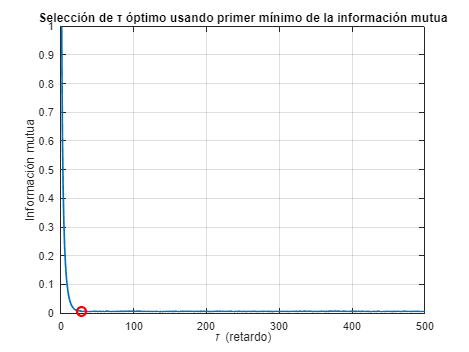

tau_opt = 28




% Suponiendo que quieres probar hasta tau = 500
max_tau = 500;
n_bins = 32; % Número de bins para la discretización (ajustable)

tau_opt = optimal_tau_mutual_information(x1, max_tau, n_bins);

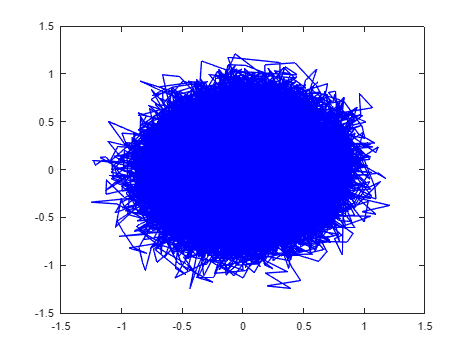


embedding_dim = 3;
X = [];
for i = 1:(N - (embedding_dim - 1) * tau_opt)
    X = [X; x1(i), x1(i + tau_opt), x1(i + 2 * tau_opt)];
end

figure;
plot(X(:,1), X(:,2), 'b');

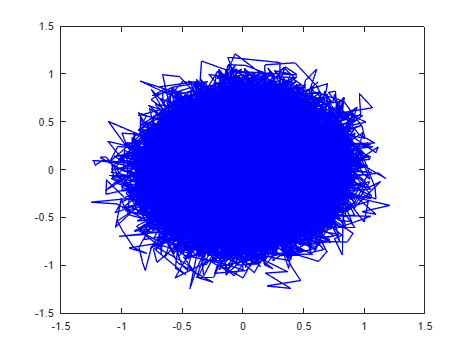

plot(X(:,2), X(:,3), 'b');

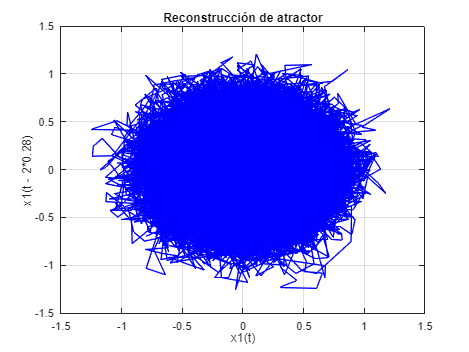

plot(X(:,1), X(:,3), 'b');
xlabel('x1(t)');
ylabel(['x1(t - 2*' num2str(tau_opt * dt) ')']);
title('Reconstrucción de atractor');
grid on;

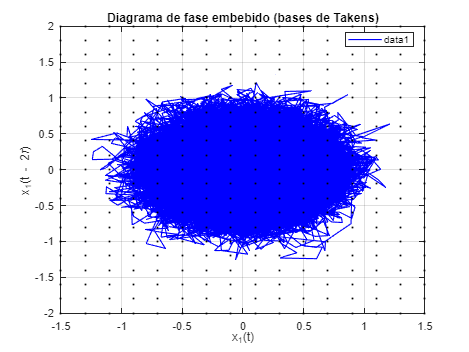

%% ——— 1) Diagrama embebido + mallado ———
coords = [ X(:,1), X(:,3) ];   % tus datos embebidos: (x1(t), x1(t-2*tau))

% Definimos la malla automática
step_emb = 0.2; 
x_min_emb = -1.5;  x_max_emb = 1.5;
y_min_emb = -2;    y_max_emb = 2;
x_vals_emb = x_min_emb:step_emb:x_max_emb;
y_vals_emb = y_min_emb:step_emb:y_max_emb;
[Xg, Yg] = meshgrid(x_vals_emb, y_vals_emb);

% 1ª figura: trayectoria embebida + mallado
figure;
plot( X(:,1), X(:,3), '-b', 'LineWidth',1 );
hold on;
plot(Xg, Yg, 'k.', 'MarkerSize',5, 'HandleVisibility','off');
xlabel('x_1(t)'); 
ylabel(['x_1(t - 2\tau)']);
title('Diagrama de fase embebido (bases de Takens)');
legend('Location','best');
grid on;

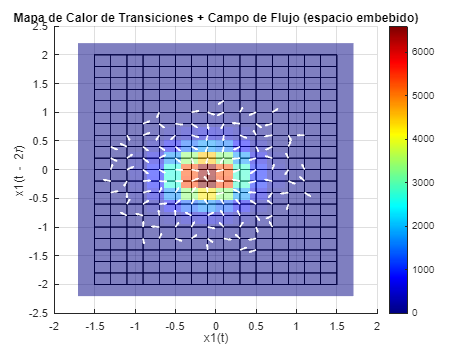


%% ———  Mapa de calor + Campo de flujo en espacio embebido  ———
% Variables embebidas
x1_emb = X(:,1);
x2_emb = X(:,3);

% Parámetros de la malla (idénticos a tu diagrama original)
step_size = 0.2;
x_min = -1.5; x_max = 1.5;
y_min = -2;   y_max = 2;
x_vals = x_min:step_size:x_max;
y_vals = y_min:step_size:y_max;

% Inicializar conteos y mapa de tiempos
transition_counts_emb = zeros(length(x_vals), length(y_vals));
time_passes_emb     = containers.Map('KeyType','char','ValueType','any');

% Recorremos la trayectoria embebida y acumulamos
for i = 1:numel(x1_emb)-1
    % A qué celda cae
    ix = floor( (x1_emb(i) - x_min)/step_size ) + 1;
    iy = floor( (x2_emb(i) - y_min)/step_size ) + 1;
    if ix<1 || ix>length(x_vals) || iy<1 || iy>length(y_vals)
        continue
    end

    key = sprintf('%d,%d', ix, iy);
    % contamos
    transition_counts_emb(ix,iy) = transition_counts_emb(ix,iy) + 1;
    % guardamos paso
    if isKey(time_passes_emb, key)
        time_passes_emb(key) = [time_passes_emb(key), i];
    else
        time_passes_emb(key) = i;
    end
end

% Ahora dibujamos el heatmap + flujo exactamente igual a tu código original

figure;
hold on;
grid on;

% dibujamos la cuadrícula
for xi = x_vals
    plot([xi xi],[y_min y_max],'k-','LineWidth',0.5);
end
for yj = y_vals
    plot([x_min x_max],[yj yj],'k-','LineWidth',0.5);
end

% heatmap
imagesc([x_min-step_size/2, x_max+step_size/2], ...
        [y_min-step_size/2, y_max+step_size/2], ...
        transition_counts_emb');
set(gca,'YDir','normal');
colormap(jet);
colorbar;
alpha(0.5);

% campo de flujo
quiver_scale = 0.1;
keys_list = keys(time_passes_emb);
for idx = 1:numel(keys_list)
    key = keys_list{idx};
    cell_coords = sscanf(key,'%d,%d');
    times = time_passes_emb(key);
    vectors = [];
    for j = 1:numel(times)
        t0 = times(j);
        if t0<2 || t0>=numel(x1_emb), continue, end
        % mira si sale de la celda en el siguiente paso
        ix0 = floor((x1_emb(t0)-x_min)/step_size)+1;
        iy0 = floor((x2_emb(t0)-y_min)/step_size)+1;
        ix1 = floor((x1_emb(t0+1)-x_min)/step_size)+1;
        iy1 = floor((x2_emb(t0+1)-y_min)/step_size)+1;
        if ix0~=ix1 || iy0~=iy1
            d1 = [ x1_emb(t0+1)-x1_emb(t0),   x2_emb(t0+1)-x2_emb(t0) ];
            d2 = [ x1_emb(t0)-x1_emb(t0-1),   x2_emb(t0)-x2_emb(t0-1) ];
            vectors(end+1,:) = d1 + d2; %#ok<SAGROW>
        end
    end
    if ~isempty(vectors)
        mv = mean(vectors,1);
        if norm(mv)>0
            mv = mv/norm(mv);
        end
        quiver( ...
          x_min + (cell_coords(1)-1)*step_size, ...
          y_min + (cell_coords(2)-1)*step_size, ...
          mv(1)*quiver_scale, mv(2)*quiver_scale, ...
          'w','LineWidth',1.5,'MaxHeadSize',2 );
    end
end

xlabel('x1(t)');        
ylabel(['x1(t - 2\tau)']);
title ('Mapa de Calor de Transiciones + Campo de Flujo (espacio embebido)');
hold off;